%% ====================================================================
%  INDIVIDUAL-TO-GROUP GRADIENT SIMILARITY (LEAVE-ONE-OUT)
%  Three reference means: Combined, YA-only, OA-only
%  Run this AFTER gm_ya, gm_oa, gm_combined are computed
%  ====================================================================

fprintf('\n========================================\n');

fprintf('  INDIVIDUAL-TO-GROUP GRADIENT SIMILARITY (LOO)\n');

  INDIVIDUAL-TO-GROUP GRADIENT SIMILARITY (LOO)


fprintf('========================================\n');


nYA    = length(YA_ind);

Unrecognized function or variable 'YA_ind'.

nOA    = length(OA_ind);
nAll   = nYA + nOA;
nGrads = 2;  % G1 and G2

%% ── Extract individual gradient matrices ──────────────────────────────

% YA_grads: nYA x ROIs x nGrads
YA_grads = zeros(nYA, ROIs, nGrads);
for i = 1:nYA
    YA_grads(i, :, :) = gm_ya.aligned{i}(:, 1:nGrads);
end

% OA_grads: nOA x ROIs x nGrads
OA_grads = zeros(nOA, ROIs, nGrads);
for i = 1:nOA
    OA_grads(i, :, :) = gm_oa.aligned{i}(:, 1:nGrads);
end

% ALL_grads: nAll x ROIs x nGrads
% Use gm_combined if available, otherwise stack YA and OA
% Option A: from gm_combined (aligned to same reference)
ALL_grads = zeros(nAll, ROIs, nGrads);
for i = 1:nAll
    ALL_grads(i, :, :) = gm_combined_neutral.aligned{i}(:, 1:nGrads);
end

% Option B: if you prefer stacking (comment out Option A, uncomment below)
% ALL_grads = cat(1, YA_grads, OA_grads);

fprintf('Extracted: %d YA, %d OA, %d combined\n', nYA, nOA, nAll);

%% ── LOO individual-to-group similarity ────────────────────────────────

for g = 1:nGrads
    
    fprintf('\n--- G%d ---\n', g);
    fprintf('  %-22s %-8s %-10s %-10s %-10s %-10s %-10s %-10s\n', ...
        'Reference', 'Group', 'Mean r', 'Median r', 'SD', 'Min r', 'Max r', '% r>.30');
    fprintf('  %-22s %-8s %-10s %-10s %-10s %-10s %-10s %-10s\n', ...
        '----------', '-----', '------', '--------', '----', '-----', '-----', '-------');
    
    %% 1) Each individual vs COMBINED mean (LOO, N=140)
    r_vs_combined = zeros(nAll, 1);
    for i = 1:nAll
        others   = setdiff(1:nAll, i);
        loo_mean = mean(squeeze(ALL_grads(others, :, g)), 1)';
        indiv    = squeeze(ALL_grads(i, :, g))';
        r_vs_combined(i) = corr(indiv, loo_mean, 'Type', 'Spearman');
    end
    r_vs_combined_YA = r_vs_combined(1:nYA);
    r_vs_combined_OA = r_vs_combined(nYA+1:end);
    
    %% 2) Each YA vs YA-ONLY mean (LOO, n=72)
    r_vs_own_YA = zeros(nYA, 1);
    for i = 1:nYA
        others   = setdiff(1:nYA, i);
        loo_mean = mean(squeeze(YA_grads(others, :, g)), 1)';
        indiv    = squeeze(YA_grads(i, :, g))';
        r_vs_own_YA(i) = corr(indiv, loo_mean, 'Type', 'Spearman');
    end
    
    %% 3) Each OA vs OA-ONLY mean (LOO, n=68)
    r_vs_own_OA = zeros(nOA, 1);
    for i = 1:nOA
        others   = setdiff(1:nOA, i);
        loo_mean = mean(squeeze(OA_grads(others, :, g)), 1)';
        indiv    = squeeze(OA_grads(i, :, g))';
        r_vs_own_OA(i) = corr(indiv, loo_mean, 'Type', 'Spearman');
    end
    
    %% Print: vs Combined
    fprintf('  %-22s %-8s %-10.3f %-10.3f %-10.3f %-10.3f %-10.3f %-10.1f\n', ...
        'vs Combined mean', 'Young', mean(r_vs_combined_YA), median(r_vs_combined_YA), ...
        std(r_vs_combined_YA), min(r_vs_combined_YA), max(r_vs_combined_YA), ...
        100*sum(r_vs_combined_YA > 0.30)/nYA);
    fprintf('  %-22s %-8s %-10.3f %-10.3f %-10.3f %-10.3f %-10.3f %-10.1f\n', ...
        'vs Combined mean', 'Old', mean(r_vs_combined_OA), median(r_vs_combined_OA), ...
        std(r_vs_combined_OA), min(r_vs_combined_OA), max(r_vs_combined_OA), ...
        100*sum(r_vs_combined_OA > 0.30)/nOA);
    
    %% Print: vs Own group
    fprintf('  %-22s %-8s %-10.3f %-10.3f %-10.3f %-10.3f %-10.3f %-10.1f\n', ...
        'vs YA-only mean', 'Young', mean(r_vs_own_YA), median(r_vs_own_YA), ...
        std(r_vs_own_YA), min(r_vs_own_YA), max(r_vs_own_YA), ...
        100*sum(r_vs_own_YA > 0.30)/nYA);
    fprintf('  %-22s %-8s %-10.3f %-10.3f %-10.3f %-10.3f %-10.3f %-10.1f\n', ...
        'vs OA-only mean', 'Old', mean(r_vs_own_OA), median(r_vs_own_OA), ...
        std(r_vs_own_OA), min(r_vs_own_OA), max(r_vs_own_OA), ...
        100*sum(r_vs_own_OA > 0.30)/nOA);
    
    %% Wilcoxon tests
    [p1, ~, s1] = ranksum(r_vs_combined_YA, r_vs_combined_OA);
    fprintf('  Wilcoxon (vs combined): z = %.2f, p = %.4f\n', s1.zval, p1);
    
    [p2, ~, s2] = ranksum(r_vs_own_YA, r_vs_own_OA);
    fprintf('  Wilcoxon (vs own group): z = %.2f, p = %.4f\n', s2.zval, p2);
    
    %% Store
    indivToGroup.(sprintf('G%d', g)).vs_combined_YA = r_vs_combined_YA;
    indivToGroup.(sprintf('G%d', g)).vs_combined_OA = r_vs_combined_OA;
    indivToGroup.(sprintf('G%d', g)).vs_own_YA      = r_vs_own_YA;
    indivToGroup.(sprintf('G%d', g)).vs_own_OA      = r_vs_own_OA;
    indivToGroup.(sprintf('G%d', g)).p_combined      = p1;
    indivToGroup.(sprintf('G%d', g)).z_combined      = s1.zval;
    indivToGroup.(sprintf('G%d', g)).p_own            = p2;
    indivToGroup.(sprintf('G%d', g)).z_own            = s2.zval;
end

%% ── Save ──────────────────────────────────────────────────────────────
save(fullfile(data_dir, 'indivToGroup_LOO_similarity.mat'), 'indivToGroup');
fprintf('\nSaved to: %sindivToGroup_LOO_similarity.mat\n', data_dir);

%% ── Violin plots ─────────────────────────────────────────────────────

col_ya = [0.31 0.51 0.74];
col_oa = [0.80 0.40 0.30];

fig = figure('Color','w');
set(fig, 'Units','centimeters','Position',[2 2 24 12]);

xPos     = [1 2 3.5 4.5];
colors_4 = [col_ya; col_oa; col_ya; col_oa];
alphas   = [0.30, 0.30, 0.15, 0.15];

for g = 1:nGrads
    
    ax = subplot(1, nGrads, g);
    hold on;
    
    data = {indivToGroup.(sprintf('G%d', g)).vs_combined_YA, ...
            indivToGroup.(sprintf('G%d', g)).vs_combined_OA, ...
            indivToGroup.(sprintf('G%d', g)).vs_own_YA, ...
            indivToGroup.(sprintf('G%d', g)).vs_own_OA};
    
    for t = 1:4
        d     = data{t};
        c_col = colors_4(t,:);
        
        % Kernel density
        [f, xi] = ksdensity(d, 'Bandwidth', 0.05);
        f_norm  = f / max(f) * 0.35;
        
        % Filled violin
        fill([xPos(t)-f_norm, fliplr(xPos(t)+f_norm)], ...
             [xi, fliplr(xi)], c_col, ...
             'FaceAlpha', alphas(t), 'EdgeColor', c_col, 'LineWidth', 0.8);
        
        % IQR box
        q25 = prctile(d, 25);
        q75 = prctile(d, 75);
        bw  = 0.05;
        fill([xPos(t)-bw, xPos(t)+bw, xPos(t)+bw, xPos(t)-bw], ...
             [q25, q25, q75, q75], c_col*0.85, ...
             'FaceAlpha', 0.5, 'EdgeColor', 'none');
        
        % Mean line
        mn = mean(d);
        plot([xPos(t)-0.10 xPos(t)+0.10], [mn mn], ...
             '-', 'Color', 'w', 'LineWidth', 2);
        plot([xPos(t)-0.10 xPos(t)+0.10], [mn mn], ...
             '-', 'Color', c_col*0.6, 'LineWidth', 1.2);
        
        % Median dot
        md = median(d);
        plot(xPos(t), md, 'o', ...
             'MarkerFaceColor', 'w', ...
             'MarkerEdgeColor', c_col*0.5, ...
             'MarkerSize', 4, 'LineWidth', 1);
        
        % Individual data points
        rng(42);
        jitter = 0.05 * randn(length(d), 1);
        scatter(xPos(t) + jitter, d, 6, c_col, ...
                'filled', 'MarkerFaceAlpha', 0.25);
    end
    
    yline(0, ':', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.6);
    
    set(ax, 'XTick', [1.5 4], ...
            'XTickLabel', {'vs Combined mean','vs Own-group mean'}, ...
            'FontSize', 8, 'Box', 'off', 'TickDir', 'out', ...
            'TickLength', [0.02 0.02], ...
            'XLim', [0.2 5.3], ...
            'YTick', -0.2:0.2:0.8, ...
            'LineWidth', 0.8);
    xtickangle(20);
    
    ylabel(ax, 'Spearman r (individual vs. group mean)', 'FontSize', 9);
    title(ax, sprintf('G%d', g), 'FontSize', 10, 'FontWeight', 'bold');
    hold off;
end

% Legend
axes('Position', [0 0 1 1], 'Visible', 'off');
lh = gobjects(2,1);
lh(1) = patch(NaN, NaN, col_ya, 'FaceAlpha', 0.35, 'EdgeColor', col_ya);
lh(2) = patch(NaN, NaN, col_oa, 'FaceAlpha', 0.35, 'EdgeColor', col_oa);
legend(lh, {'Young adults','Older adults'}, ...
       'Location', 'southoutside', 'Orientation', 'horizontal', ...
       'FontSize', 9, 'Box', 'off');

sgtitle('Individual-to-group gradient similarity (LOO)', ...
        'FontSize', 11, 'FontWeight', 'bold');

% Save figure
out_png = fullfile(data_dir, 'indivToGroup_LOO_violins.png');
out_pdf = fullfile(data_dir, 'indivToGroup_LOO_violins.pdf');
exportgraphics(fig, out_png, 'Resolution', 300);

fprintf('\nSaved:\n  %s\n  %s\n', out_png, out_pdf);

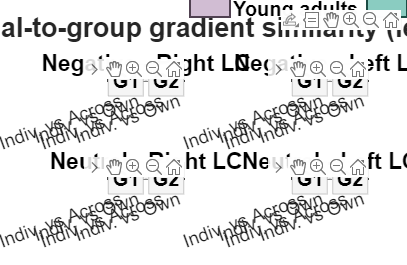

%% ====================================================================
%  INDIVIDUAL-TO-GROUP LOO: COMBINED 2x2 FIGURE — RAINCLOUD PLOT
%  Half-violin (left) + boxplot (centre) + jittered dots (right)
%  Top-left: Negative Right LC    Top-right: Negative Left LC
%  Bottom-left: Neutral Right LC  Bottom-right: Neutral Left LC
%
%  Palette: brighter purple/teal with refined dark outlines for cohesion
%  ====================================================================

clear; clc;

%% ── Paths ─────────────────────────────────────────────────────────────
base = 'E:\Gradient_Code\2mm_Results\';

mat_files = {
    fullfile(base, 'Negative\Right_LC_Study_Specific_Mask\indivToGroup_LOO_similarity.mat');
    fullfile(base, 'Negative\Left_LC_Study_Specific_Mask\indivToGroup_LOO_similarity.mat');
    fullfile(base, 'Neutral\Right_LC_Study_Specific_Mask\indivToGroup_LOO_similarity.mat');
    fullfile(base, 'Neutral\Left_LC_Study_Specific_Mask\indivToGroup_LOO_similarity.mat');
};

condTitles = {'Negative - Right LC', 'Negative - Left LC', ...
              'Neutral - Right LC',  'Neutral - Left LC'};

%% ── Typography (publication-friendly, bigger labels) ──────────────────
font_name   = 'Helvetica';
fs_tick     = 14;
fs_axlabel  = 20;
fs_title    = 17;
fs_grad     = 15;
fs_legend   = 15;
fs_suptitle = 20;

set(groot, 'defaultAxesFontName',     font_name);
set(groot, 'defaultTextFontName',     font_name);
set(groot, 'defaultAxesFontSize',     fs_tick);
set(groot, 'defaultAxesLabelFontSizeMultiplier', 1);
set(groot, 'defaultAxesTitleFontSizeMultiplier', 1);

%% ── Colours (brighter fills + deep refined outlines) ──────────────────
col_ya_base = [178 145 181] / 255;   % #B291B5
col_oa_base = [ 59 169 151] / 255;   % #3BA997

bright_w = 0.30;                                       % brighter than the original 0.18
col_ya = col_ya_base + (1 - col_ya_base) * bright_w;   % ~#CDB5CF
col_oa = col_oa_base + (1 - col_oa_base) * bright_w;   % ~#73C0B5

% Outlines: deep desaturated version of each hue — anchors brighter fills
% without looking black. Darker (~*0.45) gives a refined contrast.
edge_ya = col_ya_base * 0.45;        % ~#504169
edge_oa = col_oa_base * 0.45;        % ~#1B4C44

% Unified line weights — consistent visual weight across all marks
lw_violin   = 1.4;
lw_box      = 1.5;
lw_median   = 1.8;
lw_median_h = 3.0;     % white halo behind median
lw_whisker  = 1.1;

%% ── Layout parameters ─────────────────────────────────────────────────
xCen = [1 2 3.5 4.5   7 8 9.5 10.5];

cloud_width = 0.40;
box_hw      = 0.090;
dot_offset  = 0.17;
dot_spread  = 0.13;

y_top = 1.00;
y_lim = [0  y_top];

%% ── Figure ─────────────────────────────────────────────────────────────
fig = figure('Color','w');
set(fig, 'Units','centimeters','Position',[1 1 40 26]);

tl = tiledlayout(2, 2, 'TileSpacing', 'loose', 'Padding', 'loose');

rng(42);

for c = 1:4

    ax = nexttile(tl);
    hold(ax, 'on');

    S   = load(mat_files{c});
    res = S.indivToGroup;

    data = {
        res.G1.vs_combined_YA, res.G1.vs_combined_OA, ...
        res.G1.vs_own_YA,      res.G1.vs_own_OA, ...
        res.G2.vs_combined_YA, res.G2.vs_combined_OA, ...
        res.G2.vs_own_YA,      res.G2.vs_own_OA
    };

    face_cols = [col_ya;  col_oa;  col_ya;  col_oa; ...
                 col_ya;  col_oa;  col_ya;  col_oa];
    edge_cols = [edge_ya; edge_oa; edge_ya; edge_oa; ...
                 edge_ya; edge_oa; edge_ya; edge_oa];

    % Soft horizontal guide lines (behind data)
    for yg = 0.2:0.2:0.8
        plot([xCen(1)-0.9 xCen(end)+0.9], [yg yg], '-', ...
             'Color', [0.93 0.93 0.93], 'LineWidth', 0.6);
    end

    for t = 1:8
        d      = data{t};
        fcol   = face_cols(t,:);
        ecol   = edge_cols(t,:);
        xc     = xCen(t);

        % ── Half-violin (density cloud) on LEFT side ──────────────
        d_ref   = [d(:); -d(:)];
        [f, xi] = ksdensity(d_ref, 'Bandwidth', 0.05);
        keep    = xi >= 0;
        xi      = xi(keep);
        f       = f(keep) * 2;
        f_norm  = f / max(f) * cloud_width;

        % Filled half-violin (face only, no edge yet)
        poly_x = [xc - f_norm,  fliplr(ones(1, length(xi)) * xc)];
        poly_y = [xi,           fliplr(xi)];
        fill(poly_x, poly_y, fcol, ...
             'FaceAlpha', 0.55, 'EdgeColor', 'none');

        % Crisp outline along the curved + centre edge (single closed path)
        outline_x = [xc - f_norm,      xc * ones(1, length(xi)), xc - f_norm(1)];
        outline_y = [xi,               fliplr(xi),               xi(1)];
        plot(outline_x, outline_y, '-', ...
             'Color', ecol, 'LineWidth', lw_violin);

        % ── Boxplot (centre) ──────────────────────────────────────
        q25     = prctile(d, 25);
        q50     = median(d);
        q75     = prctile(d, 75);
        iqr_val = q75 - q25;
        whi_lo  = max(min(d), q25 - 1.5*iqr_val);
        whi_hi  = min(max(d), q75 + 1.5*iqr_val);

        % Box: stronger fill so outline reads as a confident frame
        fill([xc-box_hw, xc+box_hw, xc+box_hw, xc-box_hw], ...
             [q25, q25, q75, q75], fcol, ...
             'FaceAlpha', 0.85, 'EdgeColor', ecol, 'LineWidth', lw_box);

        % Median: white halo + dark core
        plot([xc-box_hw xc+box_hw], [q50 q50], ...
             '-', 'Color', 'w', 'LineWidth', lw_median_h);
        plot([xc-box_hw xc+box_hw], [q50 q50], ...
             '-', 'Color', ecol, 'LineWidth', lw_median);

        % Whiskers + caps
        plot([xc xc], [whi_lo q25], '-', 'Color', ecol, 'LineWidth', lw_whisker);
        plot([xc xc], [q75 whi_hi], '-', 'Color', ecol, 'LineWidth', lw_whisker);
        plot([xc-box_hw*0.55 xc+box_hw*0.55], [whi_lo whi_lo], ...
             '-', 'Color', ecol, 'LineWidth', lw_whisker);
        plot([xc-box_hw*0.55 xc+box_hw*0.55], [whi_hi whi_hi], ...
             '-', 'Color', ecol, 'LineWidth', lw_whisker);

        % ── Jittered dots on RIGHT side ───────────────────────────
        jit = dot_offset + rand(length(d), 1) * dot_spread;
        scatter(xc + jit, d, 16, fcol, ...
                'filled', 'MarkerFaceAlpha', 0.65, ...
                'MarkerEdgeColor', ecol, 'MarkerEdgeAlpha', 0.55, ...
                'LineWidth', 0.35);
    end

    % ── Soft dashed separator between G1 and G2 ───────────────────────
    sep_x = mean([xCen(4) xCen(5)]);
    plot([sep_x sep_x], [0.04 0.88], '--', ...
         'Color', [0.75 0.75 0.75], 'LineWidth', 0.8);

    % ── G1 / G2 inline pill labels ────────────────────────────────────
    text(mean(xCen(1:4)), 0.95, 'G1', 'HorizontalAlignment', 'center', ...
         'FontSize', fs_grad, 'FontWeight', 'bold', ...
         'BackgroundColor', [0.96 0.96 0.96], 'Margin', 3, ...
         'EdgeColor', [0.78 0.78 0.78]);
    text(mean(xCen(5:8)), 0.95, 'G2', 'HorizontalAlignment', 'center', ...
         'FontSize', fs_grad, 'FontWeight', 'bold', ...
         'BackgroundColor', [0.96 0.96 0.96], 'Margin', 3, ...
         'EdgeColor', [0.78 0.78 0.78]);

    % ── X-axis labels (short form) ────────────────────────────────────
    grp_x = [mean(xCen(1:2)), mean(xCen(3:4)), ...
             mean(xCen(5:6)), mean(xCen(7:8))];
    set(ax, 'XTick', grp_x, ...
            'XTickLabel', {'Indiv. vs Across','Indiv. vs Own', ...
                           'Indiv. vs Across','Indiv. vs Own'}, ...
            'FontName', font_name, ...
            'FontSize', fs_tick, ...
            'Box', 'off', 'TickDir', 'out', ...
            'TickLength', [0.012 0.012], ...
            'XLim', [xCen(1)-0.9  xCen(end)+0.9], ...
            'YLim', y_lim, ...
            'YTick', 0:0.2:0.8, ...
            'LineWidth', 1.4, ...
            'Color', 'w');
    ax.XAxis.LineWidth = 1.4;
    ax.YAxis.LineWidth = 1.4;
    ax.XColor = [0.10 0.10 0.10];
    ax.YColor = [0.10 0.10 0.10];
    xtickangle(ax, 20);

    ylabel(ax, 'Spearman''s \rho', ...
           'FontName', font_name, ...
           'FontSize', fs_axlabel, 'FontWeight', 'bold');
    title(ax, condTitles{c}, ...
          'FontName', font_name, ...
          'FontSize', fs_title, 'FontWeight', 'bold');

    hold(ax, 'off');
end

%% ── Title + Legend (top strip, key sits next to the title) ────────────
title(tl, 'Individual-to-group gradient similarity (leave-one-out)', ...
      'FontName', font_name, ...
      'FontSize', fs_suptitle, 'FontWeight', 'bold');

axes('Position', [0 0 1 1], 'Visible', 'off');
lh = gobjects(2,1);
lh(1) = patch(NaN, NaN, col_ya, 'FaceAlpha', 0.85, 'EdgeColor', edge_ya, 'LineWidth', lw_box);
lh(2) = patch(NaN, NaN, col_oa, 'FaceAlpha', 0.85, 'EdgeColor', edge_oa, 'LineWidth', lw_box);
legend(lh, {'Young adults','Older adults'}, ...
       'Position', [0.78 0.955 0.20 0.030], ...
       'Orientation', 'horizontal', ...
       'FontName', font_name, ...
       'FontSize', fs_legend, 'FontWeight', 'bold', ...
       'Box', 'off');

%% ── Save at 600 dpi ───────────────────────────────────────────────────
out_png = fullfile(base, 'indivToGroup_LOO_combined_2x2_raincloud.png');
out_pdf = fullfile(base, 'indivToGroup_LOO_combined_2x2_raincloud.pdf');
exportgraphics(fig, out_png, 'Resolution', 600);

exportgraphics(fig, out_pdf, 'ContentType', 'vector');

Error using exportgraphics
Brace indexing is not supported for variables of this type.

fprintf('\nSaved:\n  %s\n  %s\n', out_png, out_pdf);

%% ── Restore default font settings ─────────────────────────────────────
set(groot, 'defaultAxesFontName',     'remove');
set(groot, 'defaultTextFontName',     'remove');
set(groot, 'defaultAxesFontSize',     'remove');
set(groot, 'defaultAxesLabelFontSizeMultiplier', 'remove');
set(groot, 'defaultAxesTitleFontSizeMultiplier', 'remove');